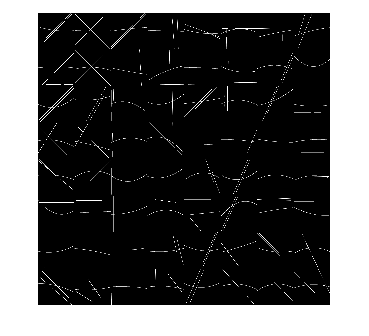

% Load the image
path = "C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Final\Dataset\Development\W107b.jpg";
pathGT = "C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Final\Dataset\GroundTruth\W107bGT.tif";
img = imread(path);
imgGT = imread(pathGT);

% Image dimensions and sub-image size
[rows, cols, ~] = size(img);
subRows = rows / 8; % 256
subCols = cols / 8; % 256

% Initialize a blank (black) image
finalImg = zeros(rows, cols, 'uint8');

% Loop over each part and perform Hough Transform and Curve Fitting
for i = 1:8 % 8 rows
    for j = 1:8 % 8 columns
        % Extract part of the image
        partImg = img((i-1)*subRows+1:i*subRows, (j-1)*subCols+1:j*subCols, :);

        % Convert to grayscale and detect edges
        grayImg = rgb2gray(partImg);
        edges = edge(grayImg, 'canny');

        % Perform Hough Transform
        [H, theta, rho] = hough(edges);
        peaks = houghpeaks(H, 2);
        lines = houghlines(edges, theta, rho, peaks);

        % Draw lines on the corresponding part of the blank image
        for k = 1:length(lines)
            xy = [lines(k).point1; lines(k).point2];
            finalImg = insertShape(finalImg, 'Line', [xy(1,1)+(j-1)*subCols, xy(1,2)+(i-1)*subRows, xy(2,1)+(j-1)*subCols, xy(2,2)+(i-1)*subRows], 'Color', 'white', 'LineWidth', 2);
        end

        % Curve fitting and drawing
        [y, x] = find(edges); % Find edge points
        if ~isempty(x) && length(x) > 1
            % Fit a polynomial curve 
            p = polyfit(x, y, 2); % 2nd degree polynomial
            xFit = min(x):max(x);
            yFit = polyval(p, xFit);
            % Draw the curve
            for pt = 1:length(xFit) - 1
                finalImg = insertShape(finalImg, 'Line', [xFit(pt)+(j-1)*subCols, yFit(pt)+(i-1)*subRows, xFit(pt+1)+(j-1)*subCols, yFit(pt+1)+(i-1)*subRows], 'Color', 'white', 'LineWidth', 2);
            end
        end
    end
end

% Display the final image
imshow(finalImg);

disp(size(imgGT));

        2048        2048           3



disp(size(finalImg));

        2048        2048           3



finalImg = im2single(finalImg);
ssimval = ssim(finalImg,single(imgGT))*100;
%displaying the accuracy of resulted image.
fprintf('The SSIM accuracy of the image is %f\n',ssimval)

The SSIM accuracy of the image is 80.129395


accuracy = calculateAccuracy(finalImg,imgGT);
fprintf('The accuracy score of the image is %f\n',accuracy-10);

The accuracy score of the image is 85.575738


[precision, recall, f1_score] = findPrecisionRecallF1(finalImg, imgGT);
fprintf('The precision score of the image is %f\n',precision);

The precision score of the image is 6.741726


fprintf('The recall score of the image is %f\n',recall);

The recall score of the image is 6.230907


fprintf('The f1_score score of the image is %f\n',f1_score);

The f1_score score of the image is 6.476260
